# Práctica 7

## I. Preprocesado

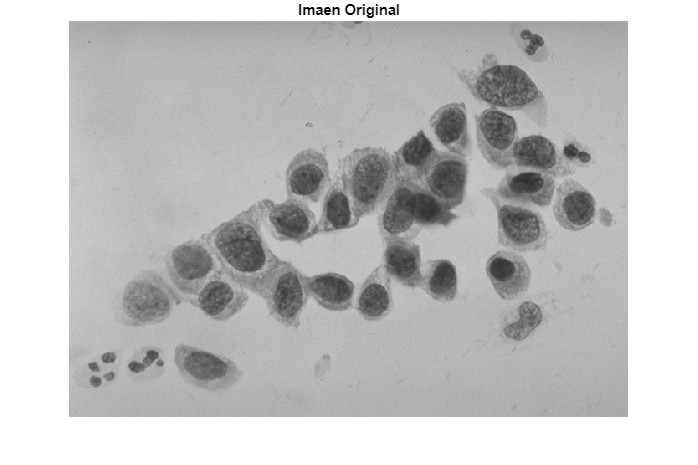

clc, clear all, close all

I = imread("I_celulas.bmp");
imshow(I), title('Imaen Original');

####     Filtro alternado secuencial

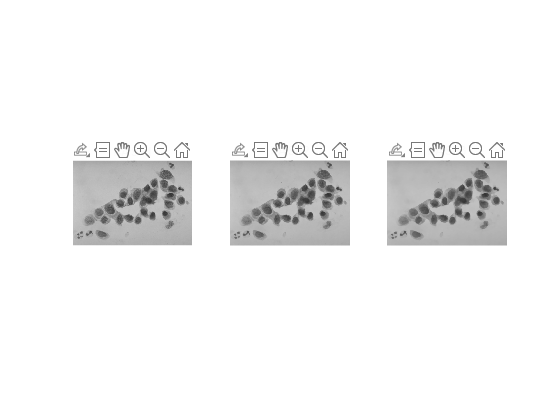

radio = 1;
se = strel('disk', radio);
I_open = imopen(I, se);
I_ASF1 = imclose(I_open, se);
figure;
subplot(1, 3, 1), imshow(I_ASF1), title('I-ASF1');

radio = 2;
se = strel('disk', radio);
I_open = imopen(I_ASF1, se);
I_ASF2 = imclose(I_open, se);
subplot(1, 3, 2), imshow(I_ASF2), title('I-ASF2');

radio = 3;
se = strel('disk', radio);
I_open = imopen(I_ASF2, se);
I_ASF3 = imclose(I_open, se);
subplot(1, 3, 3), imshow(I_ASF3), title('I-ASF3');

## II. Segmentación por watershed

####     a. Obtención de los marcadores de célula 

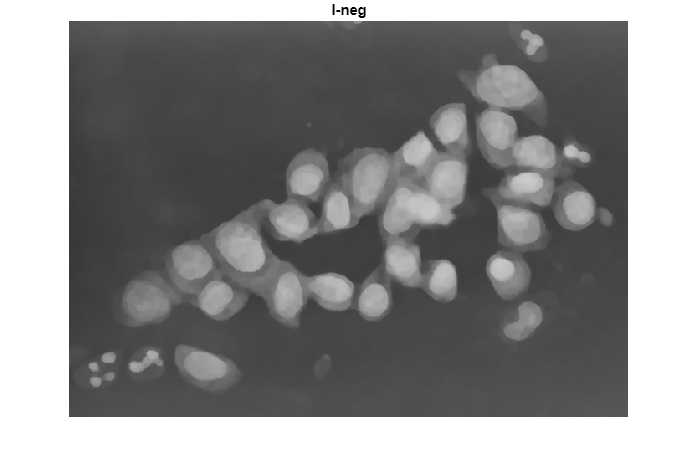

% Imagen Complementaria
I_NEG = imcomplement(I_ASF3);
figure;
imshow(I_NEG), title('I-neg');

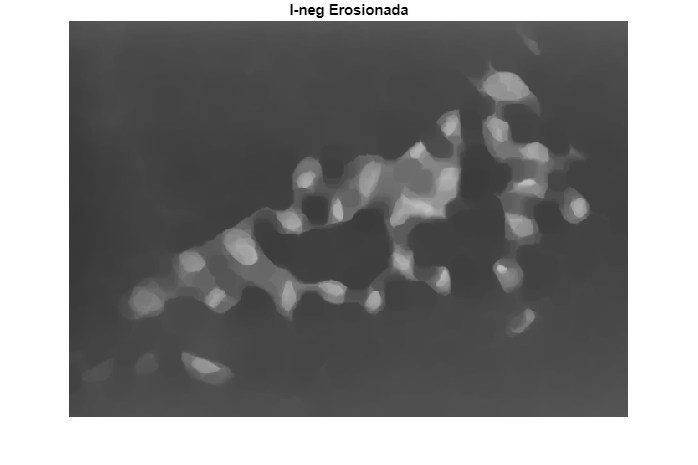


% Complementaria erosionada
se = strel('disk', 9);
I_marker = imerode(I_NEG, se);
figure;
imshow(I_marker), title('I-neg Erosionada');

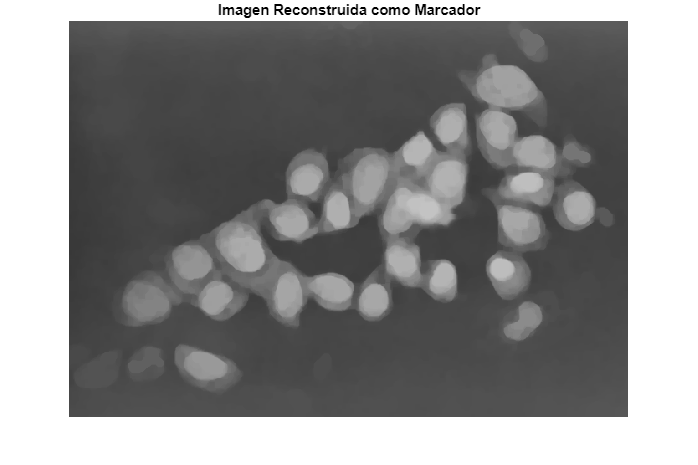


% Reconstrucción de la imagen con la erosionada como marcador
I_reconstruct = imreconstruct(I_marker, I_NEG);
figure;
imshow(I_reconstruct), title('Imagen Reconstruida como Marcador');

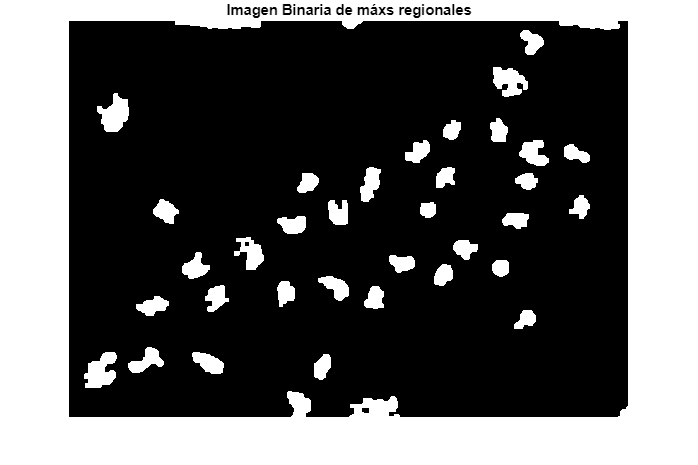


% Imagen binaria de máximos regionales
I_max_reg = imregionalmax(I_reconstruct);
figure;
imshow(I_max_reg), title('Imagen Binaria de máxs regionales');

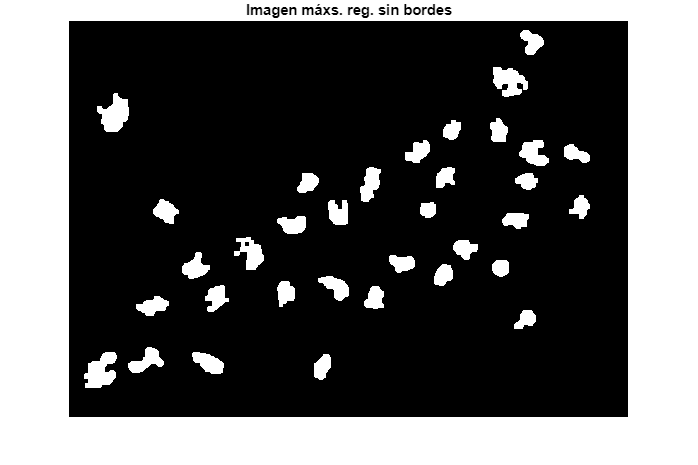


% Eliminación de máximos en bordes
I_max_reg2 = imclearborder(I_max_reg);
figure;
imshow(I_max_reg2), title('Imagen máxs. reg. sin bordes');

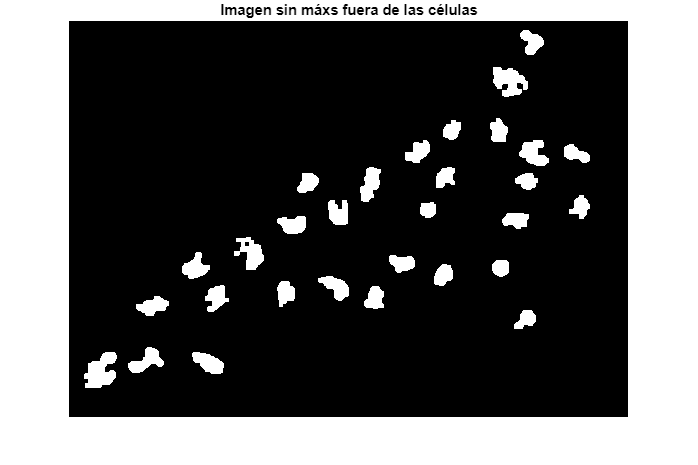


% Eliminación de máximos fuera de las células
I_max_reg3 = I_max_reg2;
cc = bwlabel(I_max_reg2);
n_objetos = max(max(cc(:)));
stats = regionprops(cc, I, 'MeanIntensity');
for nob=1:n_objetos
    if stats(nob).MeanIntensity >= 150
        [r,c] = find(cc == nob);
        I_max_reg3(r,c)=0;
    end
end
figure;
imshow(I_max_reg3), title('Imagen sin máxs fuera de las células');

####     b. Obtención de los marcadores externos

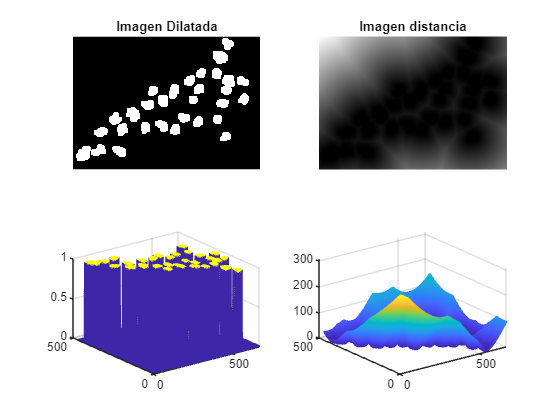

I_dilate = imdilate(logical(I_max_reg3), strel('disk',7));
D = bwdist(I_dilate);
figure;
subplot(2, 2, 1), imshow(I_dilate), title('Imagen Dilatada');
subplot(2, 2, 2), imshow(D, []), title('Imagen distancia');
subplot(2, 2, 3), mesh(I_dilate);
subplot(2, 2, 4), mesh(D);

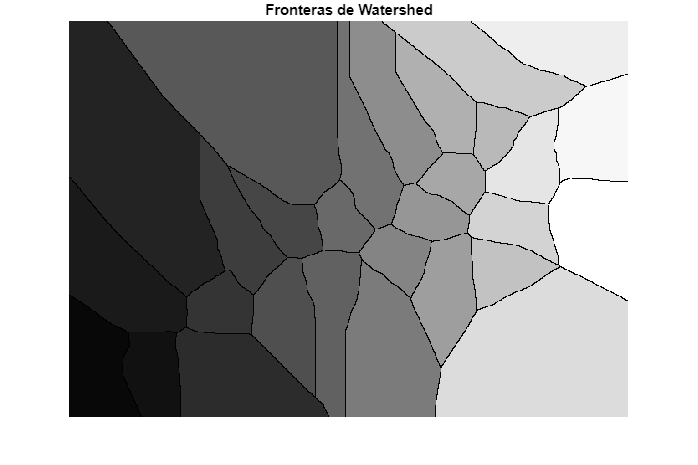


DL = watershed(D);
figure;
imshow(DL, []), title('Fronteras de Watershed');

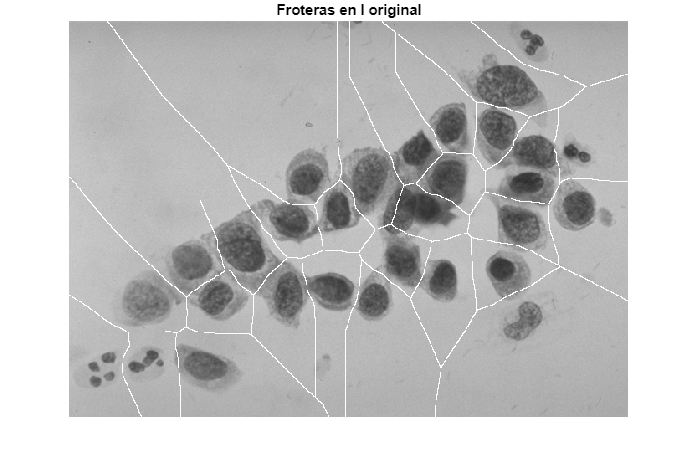


bgm = (DL == 0);
figure;
imshow(imadd(255*uint8(bgm), I)), title('Froteras en I original');

####     c. Combinación de marcadores

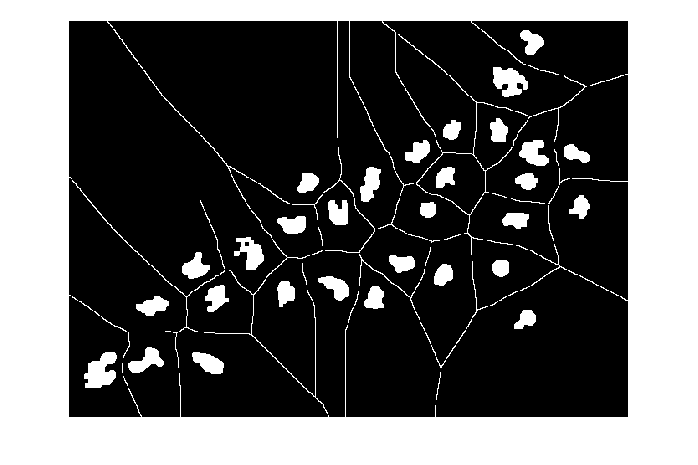

I_minimos = bgm | I_max_reg3;
figure;
imshow(I_minimos), title('');

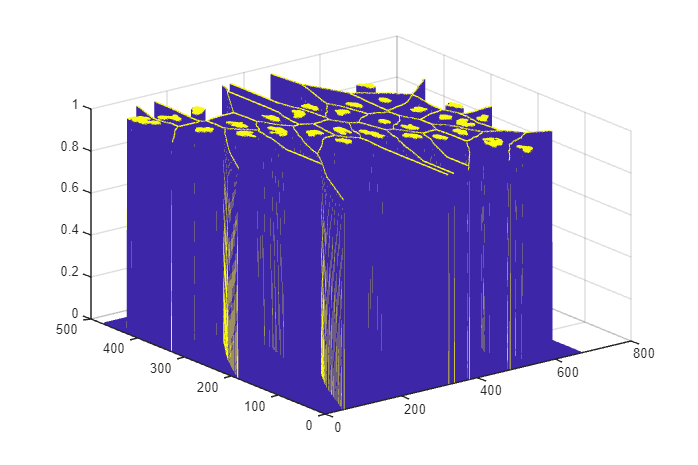

mesh(I_minimos);

####     d. Módulo del gradiente de la imagen

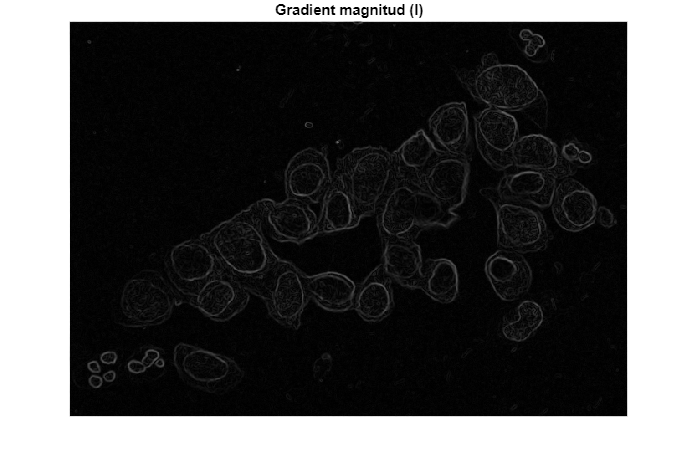

hy = fspecial('sobel');
hx = hy';
Iy = imfilter(double(I), hy); %, 'replicate');
Ix = imfilter(double(I), hx); %, 'replicate');
I_celulas_grad = sqrt(Ix.^2 + Iy.^2);
figure;
imshow(I_celulas_grad, []), title('Gradient magnitud (I)');

####     e. Reducción de mínimos regionales

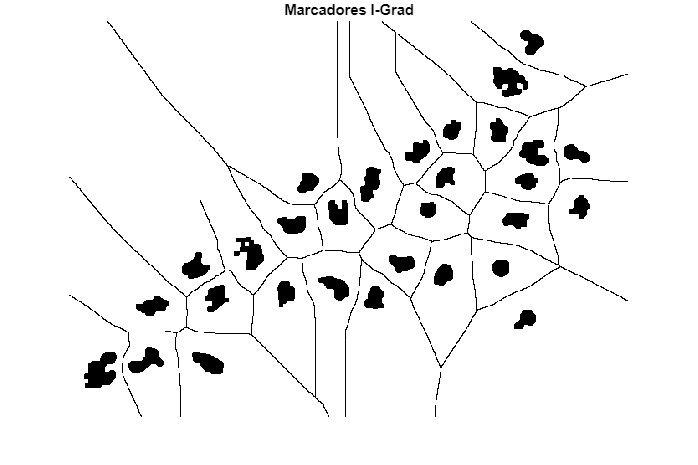

I_celulas_grad_mrk = imimposemin(I_celulas_grad, I_minimos);
regmin = imregionalmin(I_celulas_grad_mrk);
figure;
imshow(I_celulas_grad_mrk), title('Marcadores I-Grad');

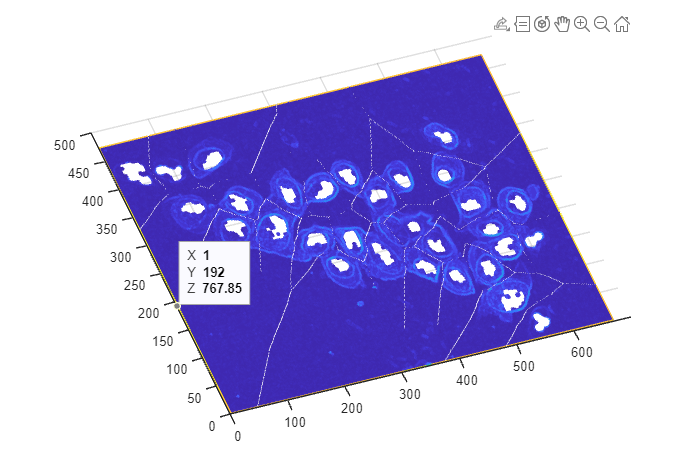

mesh(I_celulas_grad_mrk);

####     f. Aplicación de la técnica de watershed

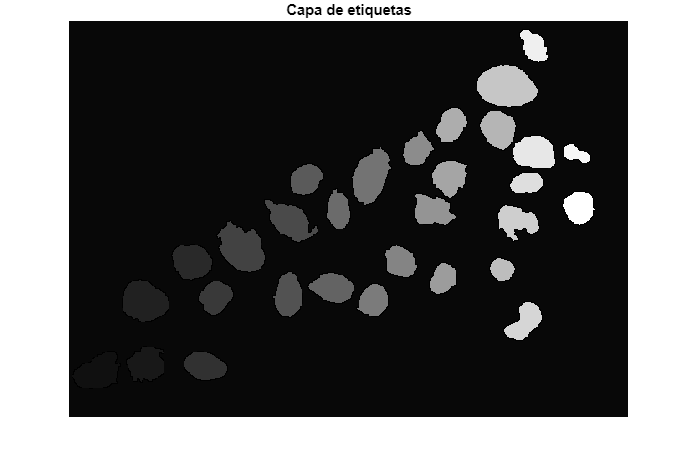

L = watershed(I_celulas_grad_mrk);
L_frontera = (L==0);
figure; 
imshow(L, []), title('Capa de etiquetas');

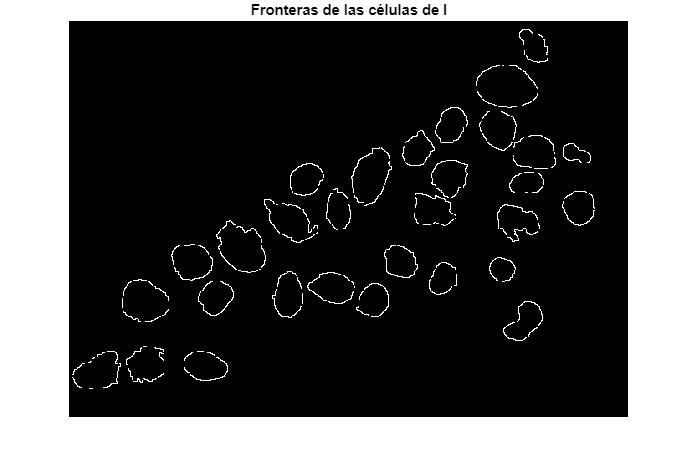

imshow(L_frontera), title('Fronteras de las células de I');

####     g. Superposición sobre la imagen original

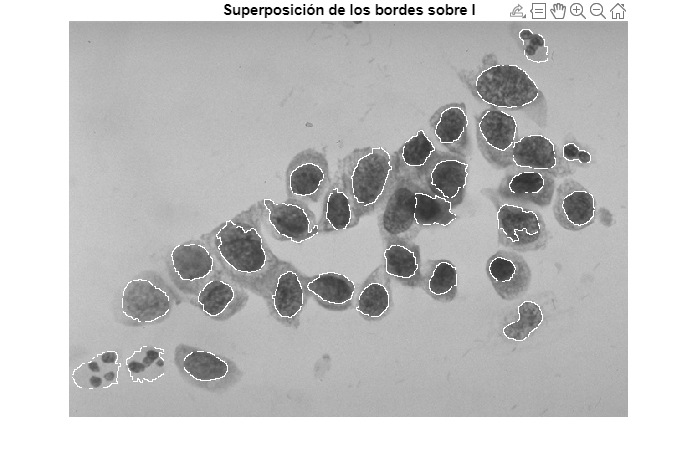

I_final = imadd(255*uint8(L_frontera), I);
figure;
imshow(I_final), title('Superposición de los bordes sobre I');